# King_ZVU.mat Data Cleaning

King Building Hallway Run, with Zero Velocity Updates

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc
addpath("Nav_Functions")

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 13.5; % Time spent sitting still before test for initialization

% Load Raw Data
load("King_ZVU_raw.mat")

## Accelerometer Data Cleaning

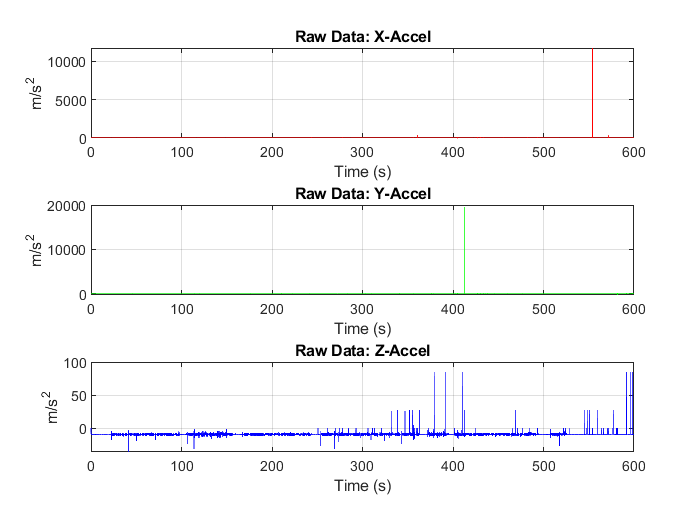

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

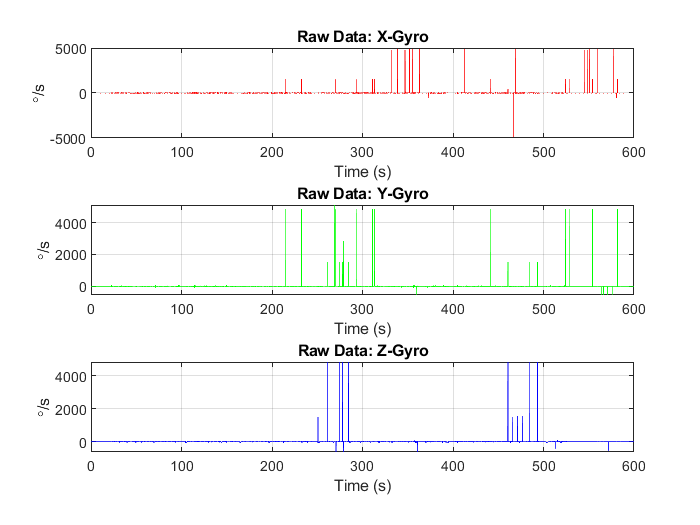

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

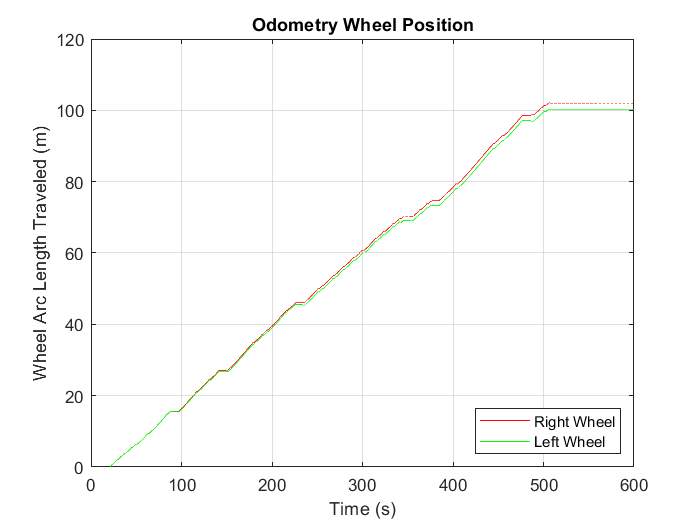

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

% Convert Depth Data into XYZ Coordinates
[kinect_samples, ~] = size(depth);
xyz = zeros(3, 3072, kinect_samples);

for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz_lowRes(depth, k);
end

## Depth Camera Animation

% % Show Animation
% for k = 1 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

save("SBT_CCW.mat", "Fs", "dt", "init_time", "t", "accel", "gyro", "odo", "xyz")